# MAP estimation for the Poisson distribution

It is believed that the data set

x=[80 92 87 95 97]

x =     80    92    87    95    97


is distributed by the Poisson distribution with an unknown parameter $\lambda$. First, we establish the maximum likelihood estimate for $\lambda$.

lambdaMLE=mle(x,"distribution","Poisson")

lambdaMLE = 90.2000

Construct a gamma distribution prior for lambda

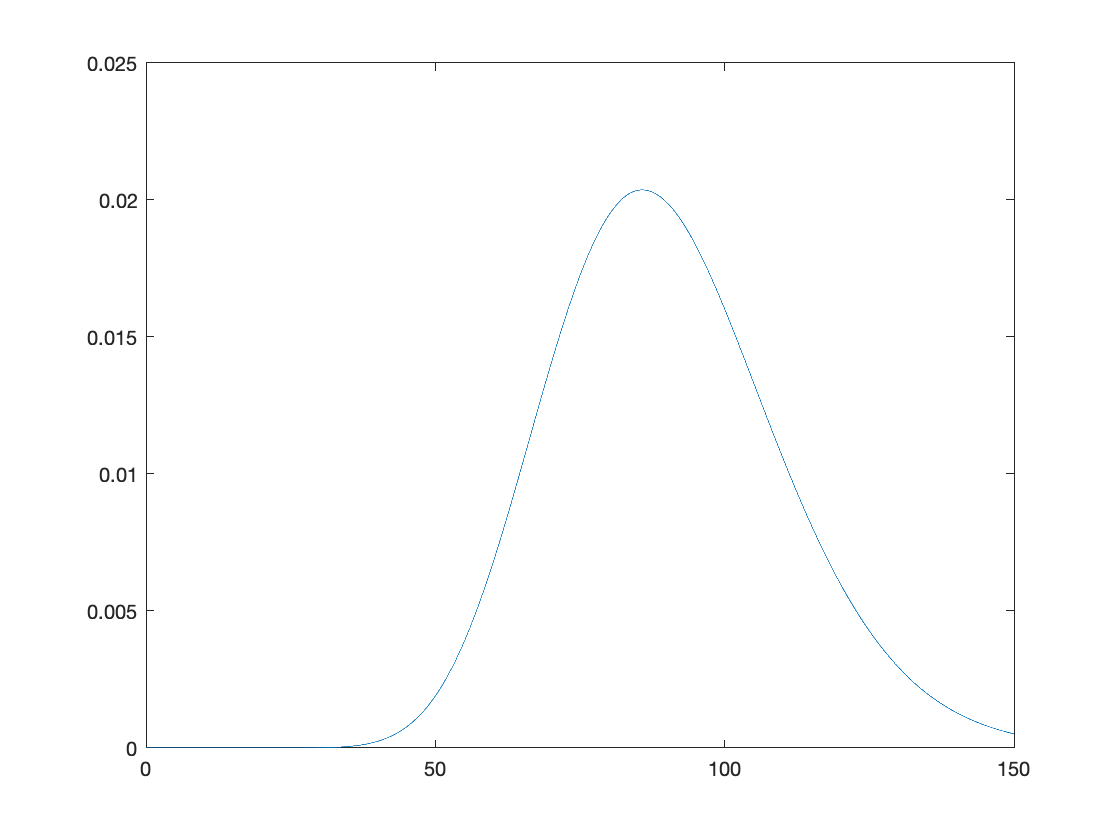

mu=lambdaMLE;    %subjective guess at expected value for lambda
sigma=20;   %subjective guess at variance around the expected value for lambda
k=mu^2/sigma^2;
th=sigma^2/mu;
lambda=linspace(0,150,100000);          %set of possible lambda-values
prior=gampdf(lambda,k,th);

figure(1)
p1=plot(lambda,prior);

Construct the likelihood and marginal probability

F=prod(poisspdf(repmat(x',1,length(lambda)),repmat(lambda,length(x),1)));
margin=trapz(lambda,F.*prior);

Construct the posterior probability and plot it

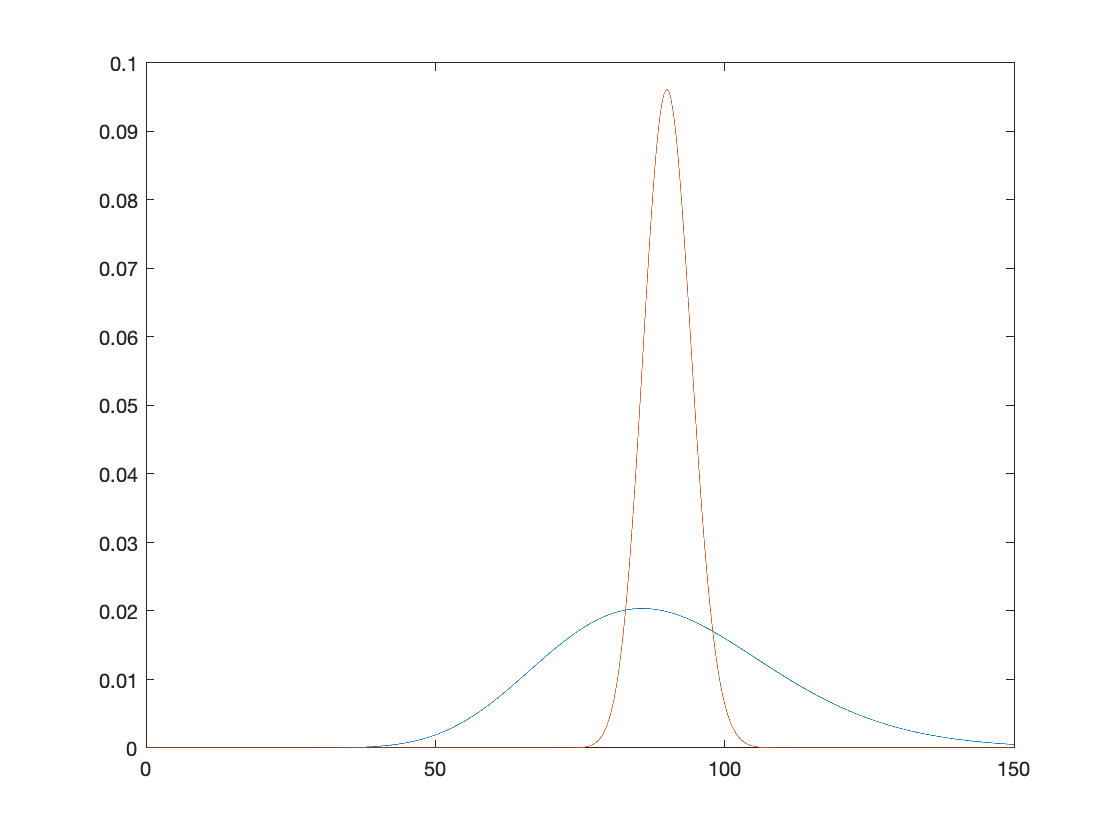

posterior=F.*prior/margin;
figure(1)
hold on
p2=plot(lambda,posterior);
hold off

Compute the MAP estimate

[M,I]=max(posterior);
MAP=lambda(I)

MAP = 90.0084

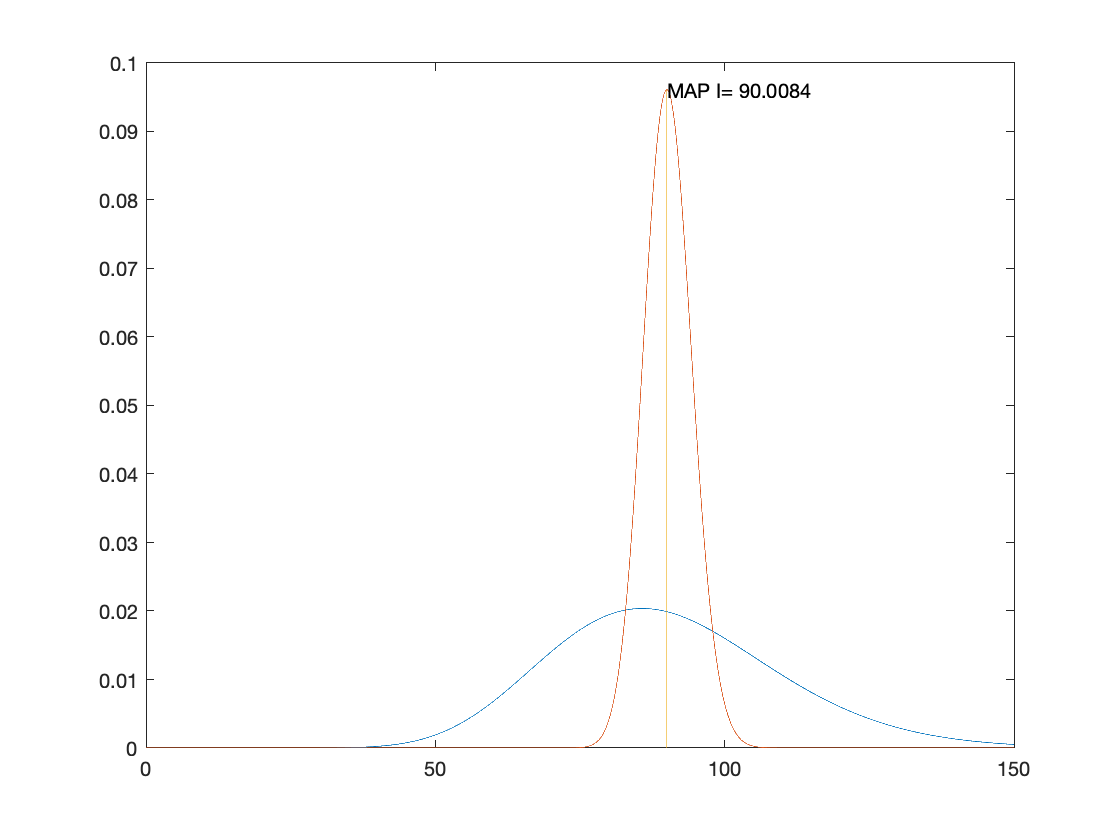

figure(1)
hold on
plot([lambda(I) lambda(I)],[0,posterior(I)]);
text(lambda(I)+.05,posterior(I),strjoin({'MAP I=',num2str(lambda(I))}))
hold off

## Round II

Collect more data in order to obtain an even more refined estimate for $\lambda$

x=[94 74 89 83 82]

x =     94    74    89    83    82


prior=posterior;
F=prod(poisspdf(repmat(x',1,length(lambda)),repmat(lambda,length(x),1)));
margin=trapz(lambda,F.*prior);
posterior=F.*prior/margin;
hold on
p3=plot(lambda,posterior);
[M,I]=max(posterior);
MAP2=lambda(I)

MAP2 = 87.2664

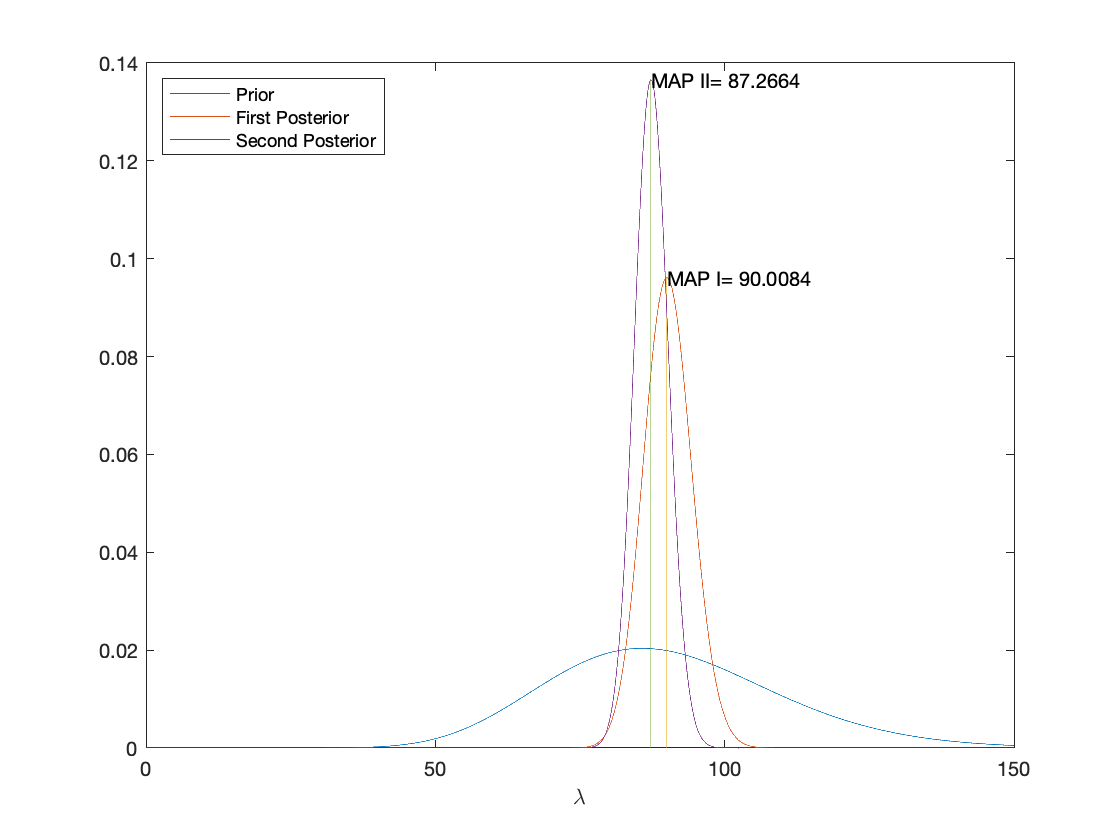

plot([lambda(I) lambda(I)],[0,posterior(I)]);
text(lambda(I)+.05,posterior(I),strjoin({'MAP II=',num2str(lambda(I))}))
legend([p1,p2,p3],'Prior','First Posterior','Second Posterior','Location','northwest')
hold off
xlabel('\lambda')